# Projekat iz predmeta prepoznavanje oblika

## Zadatak 1

Projektovati inovativni sistem za prepoznavanje pokazanih znakova zasnovan na testiranju hipoteza. 

-  Detaljno opisati algoritam za obradu slike i odabir obeležja koji prethodi samoj klasifikaciji. Algoritam treba da bude  što robusniji (na različite osvetljaje, položaje šaka, načine pokazivanja znakova itd). 

- Izvršiti podelu na trening i test skup. Rezultate klasifikacije test skupa prikazati u obliku matrice konfuzije. 

- Odabrati dva oblika i dva obeležja takva da su odabrani oblici što separabilniji u tom prostoru. Prikazati histogram  obeležja za oba slova i prokomentarisati njihov oblik. 

-  Za slova i obeležja pod c) projektovati parametarski klasifikator po izboru i iscrtati klasifikacionu liniju

clear ;
close all;
clc;
imds_scissors = imageDatastore('C:/Users/Dragana/Downloads/PO vezbe/data/scissors/*.png');
imds_paper = imageDatastore('C:/Users/Dragana/Downloads/PO vezbe/data/paper/*.png');
imds_rock = imageDatastore('C:/Users/Dragana/Downloads/PO vezbe/data/rock/*.png');
imgs_scissors = readall(imds_scissors);
imgs_paper = readall(imds_paper);
imgs_rock = readall(imds_rock);

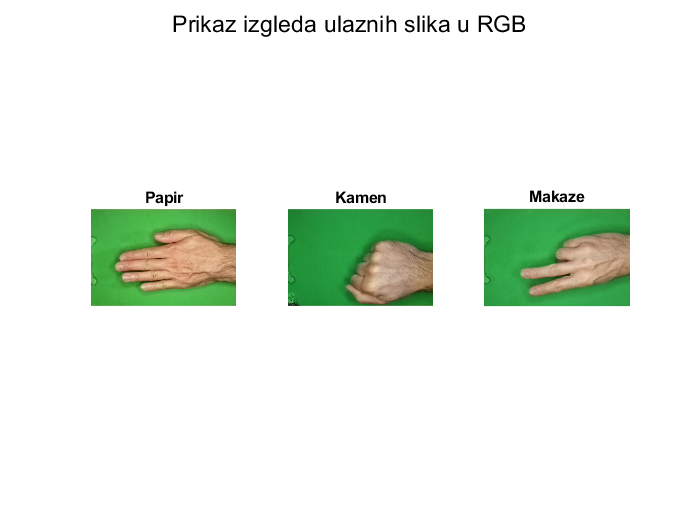

img_paper = imgs_paper{1};
img_rock = imgs_rock{1};
img_scissors = imgs_scissors{1};
fig_id = 1;
figure(fig_id)
subplot(131);imshow(img_paper, [0,255]);title('Papir');
subplot(132);imshow(img_rock, [0,255]);title('Kamen');
subplot(133);imshow(img_scissors, [0,255]);title('Makaze');
sgtitle('Prikaz izgleda ulaznih slika u RGB')

fig_id = fig_id+1;

S obzirom da je ruka coveka bez boje, ona ce se bojom uvek odvajati u odnosu na okolinu koje god boje da je sto ili odeca. Iz ovog razloga prelazimo u HSV sistem i ogranicavamo H komponentu kako bismo segmentisali deo gde je ruka. Pomocu ovako segmentisane slike mozemo izdvojiti i ivice ruke sto nam moze pomoci za izdvajanje bitnih obelezja. Ne zelimo da koristimo V komponentu jer je ona zapravo osvetljaj, pa pri razlicitim osvetljajima moze da se desi da nas algoritam radi losije.

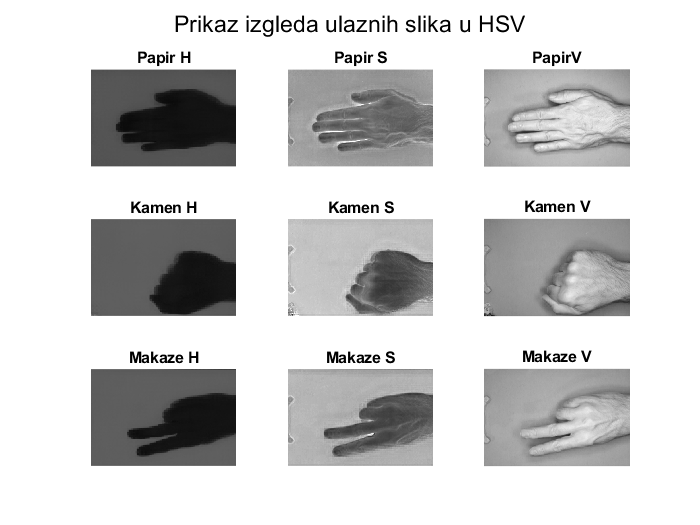

img_paper_hsv = rgb2hsv(img_paper);
img_rock_hsv = rgb2hsv(img_rock);
img_scissors_hsv = rgb2hsv(img_scissors);
figure(fig_id)
subplot(331);imshow(img_paper_hsv(:,:,1));title('Papir H');
subplot(332);imshow(img_paper_hsv(:,:,2));title('Papir S');
subplot(333);imshow(img_paper_hsv(:,:,3));title('PapirV');
subplot(334);imshow(img_rock_hsv(:,:,1));title('Kamen H');
subplot(335);imshow(img_rock_hsv(:,:,2));title('Kamen S');
subplot(336);imshow(img_rock_hsv(:,:,3));title('Kamen V');
subplot(337);imshow(img_scissors_hsv(:,:,1));title('Makaze H');
subplot(338);imshow(img_scissors_hsv(:,:,2));title('Makaze S');
subplot(339);imshow(img_scissors_hsv(:,:,3));title('Makaze V');
sgtitle('Prikaz izgleda ulaznih slika u HSV')

fig_id = fig_id+1;

S obzirom da se boja koze nalazi oko 30 stepeni kada posmatramo H vrednosti, ogranicicemo H vrednost izmedju 20 i 40 stepeni tj. ako posmatramo H komponentu od 0 do 1 - izmedju 0.0556 i 0.1111. Ovo se moze videti i sa histograma H komponenti da se manji pik nalazi na sve tri otprilike u tom opsegu vrednosti.

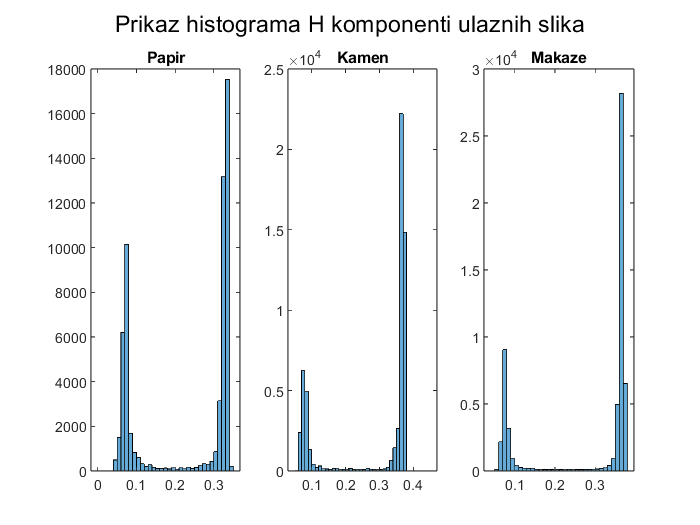

img_paper_h = img_paper_hsv(:,:,1);
img_rock_h = img_rock_hsv(:,:,1);
img_scissors_h = img_scissors_hsv(:,:,1);
figure(3)
subplot(131);histogram(img_paper_h); title('Papir');
subplot(132);histogram(img_rock_h); title('Kamen');
subplot(133);histogram(img_scissors_h); title('Makaze');
sgtitle('Prikaz histograma H komponenti ulaznih slika')

Sa histograma takodje mozemo primetiti da se broj piksela koji pripadaju ruci kod papira znatno izdvaja u odnosu na kamen i makaze. Iz tog razloga, to ce biti korisceno kao prvo obelezje pri klasifikaciji. Ovo obelezje nije skroz reprezentativno jer razlicite osobe imaju razlicitu velicinu ruke, ali dobro ce raditi u slucaju kada su ruke osoba  za koje su slikane slike slicne velicine.

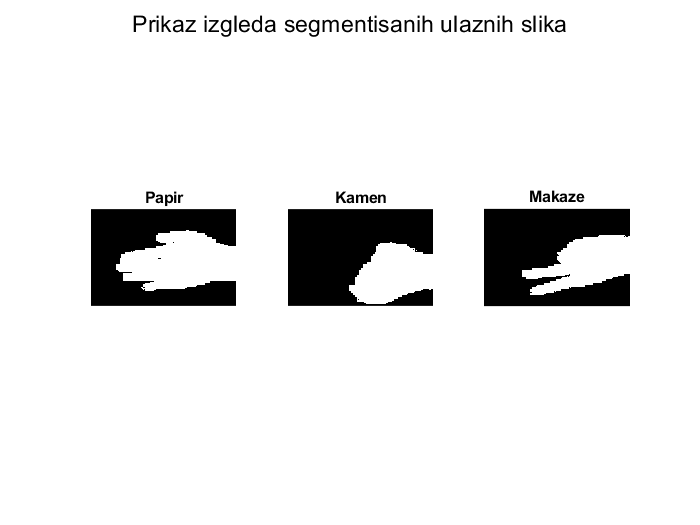

img_paper_seg = (img_paper_h>=0.04) & (img_paper_h<=0.12);
img_rock_seg = (img_rock_h>=0.04) & (img_rock_h<=0.12);
img_scissors_seg = (img_scissors_h>=0.04) & (img_scissors_h<=0.12);
figure(fig_id)
subplot(131);imshow(img_paper_seg,[0,1]); title('Papir');
subplot(132);imshow(img_rock_seg,[0,1]); title('Kamen');
subplot(133);imshow(img_scissors_seg,[0,1]); title('Makaze');
sgtitle('Prikaz izgleda segmentisanih ulaznih slika')

fig_id = fig_id+1;

Primetimo da je na prvoj slici ostala crna tackica. Zbog ovakvih situacija, da ne bismo imali rupu u segmentu primenicemo dilataciju. Ova operacija dodeljuje svakom pikselu maksimum njegove okoline cime se popunjavaju sve rupe.

se = strel("rectangle",[3 3])

se = strel is a rectangle shaped structuring element with properties:

      Neighborhood: [3×3 logical]
    Dimensionality: 2


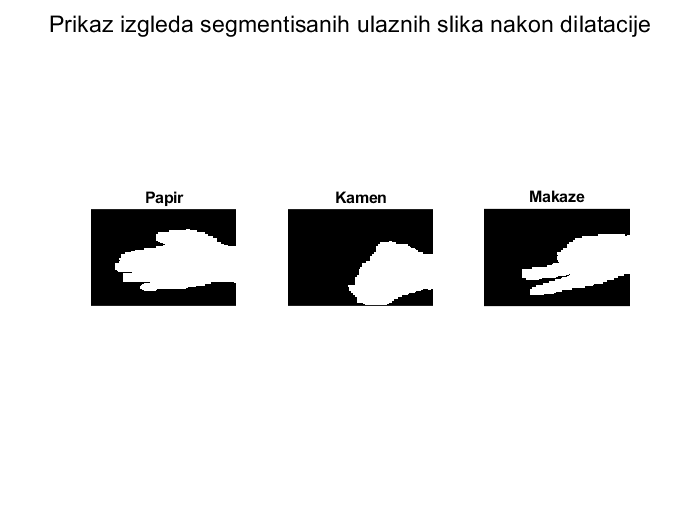

img_paper_seg = imdilate(img_paper_seg,se);
img_rock_seg= imdilate(img_rock_seg,se);
img_scissors_seg = imdilate(img_scissors_seg,se);
figure(fig_id)
subplot(131);imshow(img_paper_seg,[0,1]); title('Papir');
subplot(132);imshow(img_rock_seg,[0,1]); title('Kamen');
subplot(133);imshow(img_scissors_seg,[0,1]); title('Makaze');
sgtitle('Prikaz izgleda segmentisanih ulaznih slika nakon dilatacije')

fig_id = fig_id+1;

Naredni korak je izdvajanje ivica.

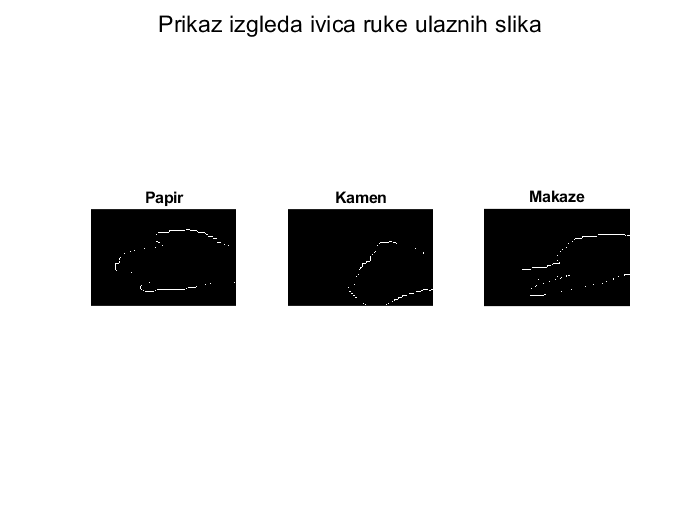

BW_paper = edge(img_paper_seg);
BW_rock = edge(img_rock_seg);
BW_scissors = edge(img_scissors_seg);
figure(fig_id)
subplot(131);imshow(BW_paper,[0,1]); title('Papir');
subplot(132);imshow(BW_rock,[0,1]); title('Kamen');
subplot(133);imshow(BW_scissors,[0,1]); title('Makaze');
sgtitle('Prikaz izgleda ivica ruke ulaznih slika')

fig_id = fig_id+1;

Sledece najintuitivnije obelezje koje mozemo iz ovoga izvuci je broj ivicnih piksela, ipak i ovo obelezje ce zavisiti od ruke, pa da bismo uklonili zavisnost od velicine ruke mozemo taj broj podeliti sa povrsinom ruke da bismo dobili relativnu velicinu ivica. Ovo obelezje bi trebalo da odvoji makaze i papir od kamena.

Naredna obelezja su najveca rasirenost ruke koja bi trebala da odvoji papir od ostalih oblika. Poslednja dva obelezja su suma piksela u kolonama koje sadrze vise od dva piksela sto bi trebalo nekako da uhvati slike gde ima vise prstiju i razlika najveceg i najmanjeg indeksa kolone koja ima vise od dva piksela sto bi trebalo da predstavlja duzinu prstiju ako se vide.

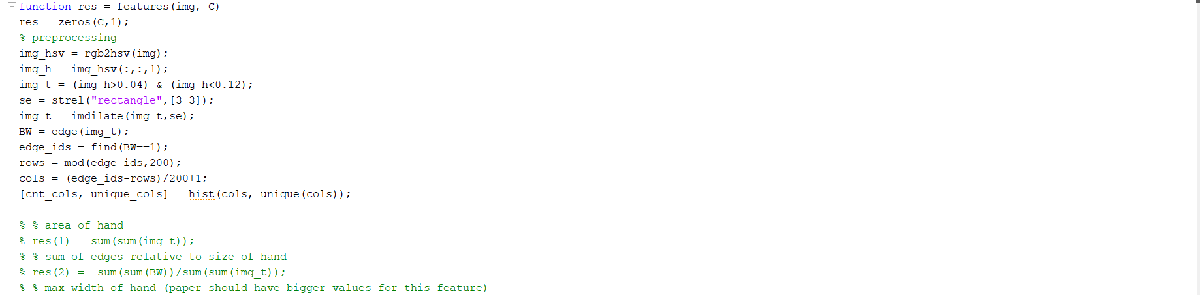

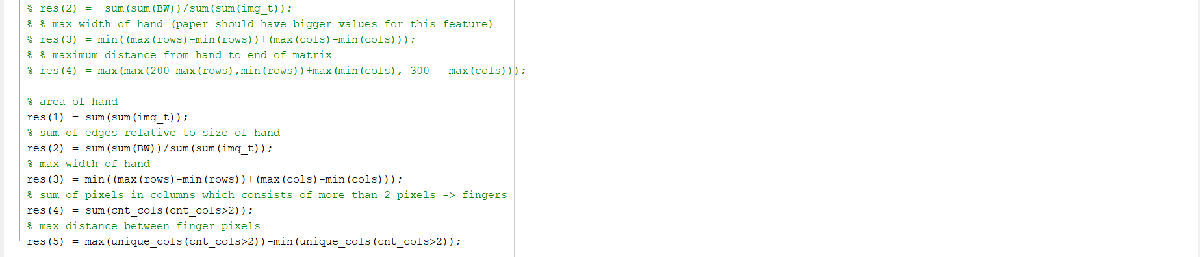

C = 5;
P = zeros(C, length(imgs_paper));
for i = 1:length(imgs_paper)
    P(:,i) = features(imgs_paper{i},C);
end
S = zeros(C, length(imgs_scissors));
for i = 1:length(imgs_scissors)
    S(:,i) = features(imgs_scissors{i},C);
   
end
R = zeros(C, length(imgs_rock));
for i = 1:length(imgs_rock)
    R(:,i) = features(imgs_rock{i},C);   
end

Odvajanje podataka na test i trening skup:

%shuffle
R = R(:, randperm(size(R, 2)));
% 30% test
R_test = R(:,1:200);
% 70% train
R_train = R(:,201:end);
%shuffle
P = P(:, randperm(size(P, 2)));
% 30% test
P_test = P(:,1:200);
% 70% train
P_train = P(:,201:end);
% shuffle
S = S(:, randperm(size(S, 2)));
% 30% test
S_test = S(:,1:200);
% 70% train
S_train = S(:,201:end);

Racunanje parametara i treniranje sa Bajesovim testom vise hipoteza se radi nad trening skupom. Bajesov test minimalne verovatnoce greske klasifikuje podatke tako sto racuna aposteriornu fgv, i onda je klasa koja se prediktuje ona cija je aposteriorna verovatnoca maksimalna.

Mp = mean(P_train,2);
Sp = cov(P_train');
Ms = mean(S_train,2);
Ss = cov(S_train');
Mr = mean(R_train,2);
Sr = cov(R_train');

Xs = [P_test, R_test, S_test];
Y_true = [ones(1,200),2*ones(1,200), 3*ones(1,200)];
Y_pred = zeros(size(Y_true));
constp = 1/(2*pi)/(det(Sp)^0.5);
consts = 1/(2*pi)/(det(Ss)^0.5);
constr = 1/(2*pi)/(det(Sr)^0.5);
Pp = 1/3%length(P)/(length(P)+length(R)+length(S));

Pp = 0.3333

Pr = 1/3%length(R)/(length(P)+length(R)+length(S));

Pr = 0.3333

Ps = 1/3%length(S)/(length(P)+length(R)+length(S));

Ps = 0.3333


for i = 1:length(Xs)
    X = Xs(:,i);
    
    f1 = constp*exp(-0.5*(X-Mp)'*inv(Sp)*(X-Mp));
    f2 = constr*exp(-0.5*(X-Mr)'*inv(Sr)*(X-Mr));
    f3 = consts*exp(-0.5*(X-Ms)'*inv(Ss)*(X-Ms));
    
    q1 = Pp*f1/(Pp*f1+Pr*f2+Ps*f3);
    q2 = Pr*f2/(Pp*f1+Pr*f2+Ps*f3);
    q3 = Ps*f3/(Pp*f1+Pr*f2+Ps*f3);
    
    [q,Y_pred(i)] = max([q1,q2,q3]);

    
end

ConMat= confusionmat(Y_true, Y_pred);
disp(['Confusion matrix on test set'])

Confusion matrix on test set


disp(ConMat)

   138    48    14
    12   179     9
    10     1   189



disp('Accuracy')

Accuracy


Vidimo da ovakav model daje zadovoljavajuce rezultate, ali da najvise gresi u slucaju papira sto ima smisla jer je papir najteze odvojiti od ostalih oblika jer moze da se javi sa rasirenim prstima kada lici na makaze i sa skupljenim prstima kada lici na kamen. Takodje, nas model najcesce mesa papir i kamen.

disp(sum(diag(ConMat))/(length(P_test)+length(R_test)+length(S_test)))

    0.8433



Sa histograma mozemo primetiti da prvo obelezje dobro odvaja papir od ostalih oblika, drugo dobro odvaja makaze od ostalih oblika, dok trece po malo odvaja sva tri, cetvrto odvaja makaze od ostalih a peto kamen od ostalih.

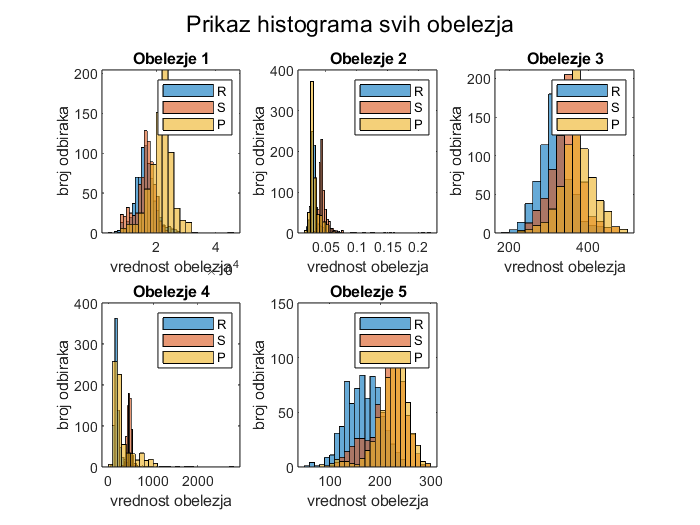

figure(fig_id)
for i = 1:C
    subplot(2,3,i);
    histogram(R(i,:));
    hold on;
    histogram(S(i,:));
    hold on;
    histogram(P(i,:));
    legend('R','S','P');
    ttl = ['Obelezje ' int2str(i)];
    xlabel('vrednost obelezja')
    ylabel('broj odbiraka')
    title(ttl);
end
sgtitle('Prikaz histograma svih obelezja')

fig_id = fig_id+1;

Kao dva dobro odvojena oblika biramo makaze i kamen, a kao dva obelezja koja ih dobro odvajaju biramo obelezja 2 i 4.

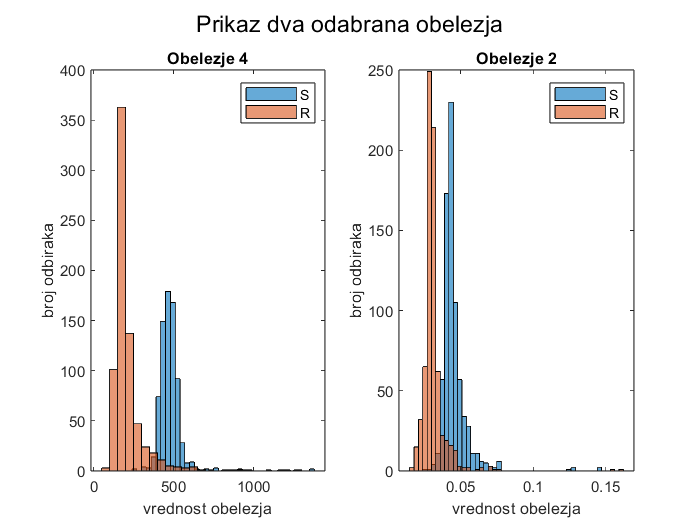

figure(fig_id)
subplot(121);histogram(S(4,:));hold on;histogram(R(4,:));
title('Obelezje 4');legend('S','R')
xlabel('vrednost obelezja')
ylabel('broj odbiraka')
subplot(122);histogram(S(2,:));hold on;histogram(R(2,:));
title('Obelezje 2'); legend('S','R')
sgtitle('Prikaz dva odabrana obelezja')
xlabel('vrednost obelezja')
 ylabel('broj odbiraka')

fig_id = fig_id+1;

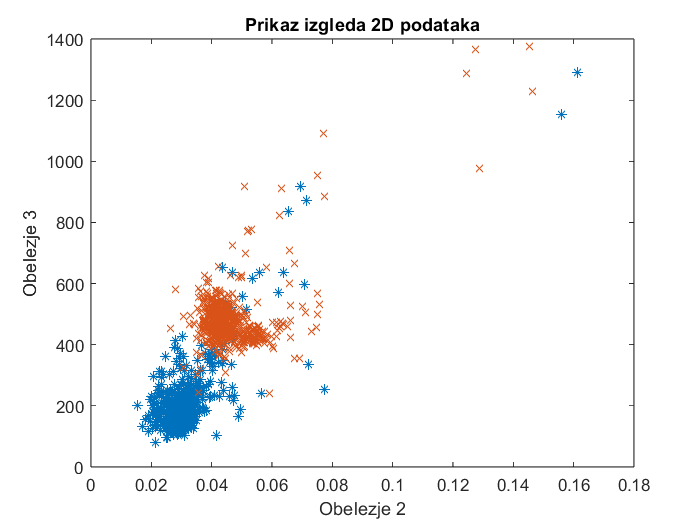

figure(fig_id)
plot(R(2,:), R(4,:), '*');
hold on;
plot(S(2,:), S(4,:),'x');
title('Prikaz izgleda 2D podataka')
xlabel('Obelezje 2')
ylabel('Obelezje 3')

fig_id = fig_id+1;

Za parametarsku klasifikaciju koristimo linearni klasifikator o kome ce vise biti reci u 3. zadatku. 

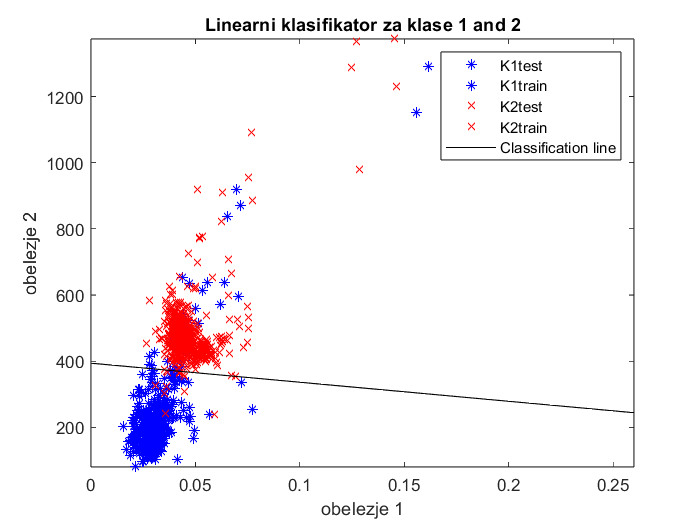

x1=0:0.01:0.26;
x2 = 200:15:600;
[V,v0] = LinearClassifier([R_test(2,:);R_test(4,:)],[R_train(2,:);R_train(4,:)],[S_test(2,:);S_test(4,:)],[S_train(2,:);S_train(4,:)],1,2,x1,x2,fig_id);

fig_id = fig_id+1;
h = (V'*[[R_test(2,:);R_test(4,:)], [S_test(2,:);S_test(4,:)]]+v0);
y_pred = zeros(1,length(P_test));
y_pred(h<=0) = 1;
y_pred(h>0) = 2;

y_true = [ones(1,200),2*ones(1,200)];
C = confusionmat(y_true, y_pred);
disp(C)

   190    10
     3   197



## Zadatak 2

Generisati po 𝑁 = 500 odbiraka iz dveju dvodimenzionih bimodalnih klasa: Ω1 ∼ 𝑃11 ⋅ 𝑁(𝑀11, Σ11) + 𝑃12 ⋅ 𝑁(𝑀12, Σ12), Ω2 ∼ 𝑃21 ⋅ 𝑁(𝑀21, Σ21) + 𝑃22 ⋅ 𝑁(𝑀22, Σ22). Parametre klasa samostalno izabrati. 

- Na dijagramu prikazati odbirke.

-  Iscrtati kako teorijski izgledaju funkcije gustine verovatnoće za raspodele klasa i uporediti ih sa histogramom  generisanih odbiraka. 

-  Projektovati Bajesov klasifikator minimalne greške i na dijagramu, zajedno sa odbircima, skicirati klasifikacionu  liniju. Uporediti grešku klasifikacije konkretnih odbiraka sa teorijskom greškom klasifikacije prve i druge vrste za  datu postavku. 

- Projektovati klasifikator minimalne cene tako da se više penalizuje pogrešna klasifikacija odbiraka iz prve klase. e) Ponoviti prethodnu tačku za Neuman-Pearson-ov klasifikator. Obrazložiti izbor 𝜀2 = 𝜀0. 

- Za klase oblika generisanih u prethodnim tačkama, projektovati Wald-ov sekvencijalni test pa skicirati zavisnost broja  potrebnih odbiraka od usvojene verovatnoće grešaka prvog, odnosno drugog tipa. 

### Prikaz odbiraka

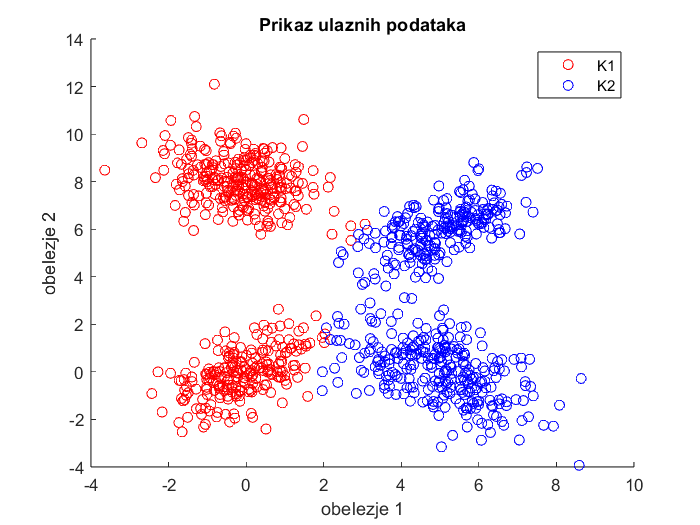

N = 500;
M11 = [0 0]';
S11 = [1 0.5; 0.5 1];
M12 = [0 8]';
S12 = [1 -0.2; -0.2 1];

M21 = [5 0]';
S21 = [1.5 -0.7; -0.7 1.5];
M22 = [5 6]';
S22 = [1 0.6; 0.6 1];

rng(20)

% first distribution
pom1 = rand(N, 1);
K11 = mvnrnd(M11,S11, N);
K12 = mvnrnd(M12,S12,N);

K1 = (pom1<0.45).*K11+(pom1>=0.45).*K12;

% second distribution
pom2 = rand(N , 1);
K21 = mvnrnd(M21,S21, N);
K22 = mvnrnd(M22,S22,N);

K2 = (pom2<0.6).*K21 + (pom2>=0.6).*K22;

figure(fig_id)
hold all;
scatter(K1(:,1),K1(:,2),'ro');
scatter(K2(:,1),K2(:,2),'bo');
title('Prikaz ulaznih podataka')
legend('K1', 'K2')
xlabel('obelezje 1')
ylabel('obelezje 2')

fig_id = fig_id+1;

### Bajesov klasifikator minimalne verovatnoce greske i procena fgv

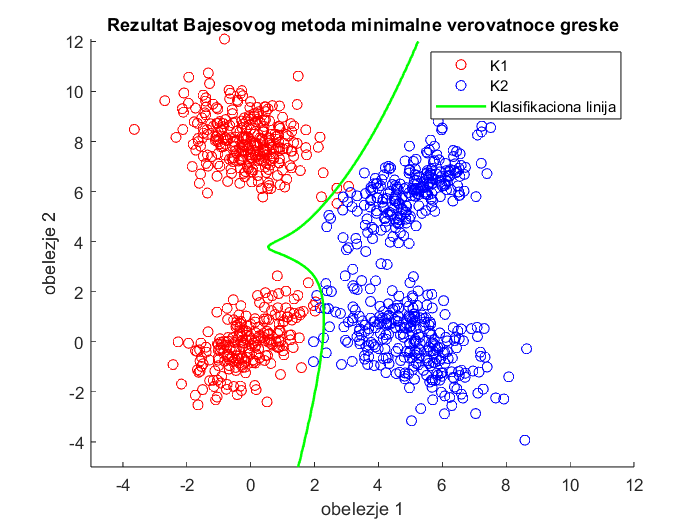

x = -5:0.1:12;
y = -5:0.1:12;

f1 = zeros(length(x), length(y));
f2 = zeros(length(x), length(y)); 
k = zeros(length(x), length(y)); 

e1_b = 0;
e2_b = 0;

const11 = 1/(2*pi)/(det(S11)^0.5);
const12 = 1/(2*pi)/(det(S12)^0.5);
const21 = 1/(2*pi)/(det(S21)^0.5);
const22 = 1/(2*pi)/(det(S22)^0.5);


for i = 1:length(x)
    for j = 1:length(y)
        X = [x(i) y(j)]';
        
        f11 = const11*exp(-0.5*(X-M11)'*inv(S11)*(X-M11));
        f12 = const12*exp(-0.5*(X-M12)'*inv(S12)*(X-M12));
        f21 = const21*exp(-0.5*(X-M21)'*inv(S21)*(X-M21));
        f22 = const22*exp(-0.5*(X-M22)'*inv(S22)*(X-M22));
        
        f1(i,j) = 0.45*f11+0.55*f12;
        f2(i,j) = 0.6*f21+0.4*f22;
        
        k(i,j) = f1(i,j)/f2(i,j);
    end
end

figure(fig_id)
hold all;
scatter(K1(:,1),K1(:,2),'ro');
scatter(K2(:,1),K2(:,2),'bo');
contour(x,y,k',[1,1],'g','LineWidth',1.5)
xlabel('obelezje 1')
ylabel('obelezje 2')
legend('K1','K2','Klasifikaciona linija')
title('Rezultat Bajesovog metoda minimalne verovatnoce greske')

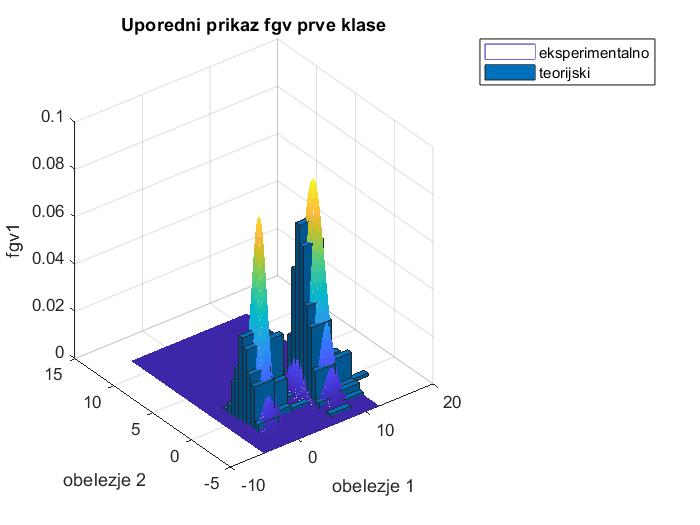

fig_id = fig_id+1;

[X,Y] = meshgrid(x,y); 
figure(fig_id)
mesh(X,Y,f1,'FaceAlpha',0.5)
hold on;
histogram2(K1(:,2),K1(:,1),'Normalization','pdf');
xlabel('obelezje 1')
ylabel('obelezje 2')
zlabel('fgv1')
title('Uporedni prikaz fgv prve klase')
legend('eksperimentalno','teorijski')

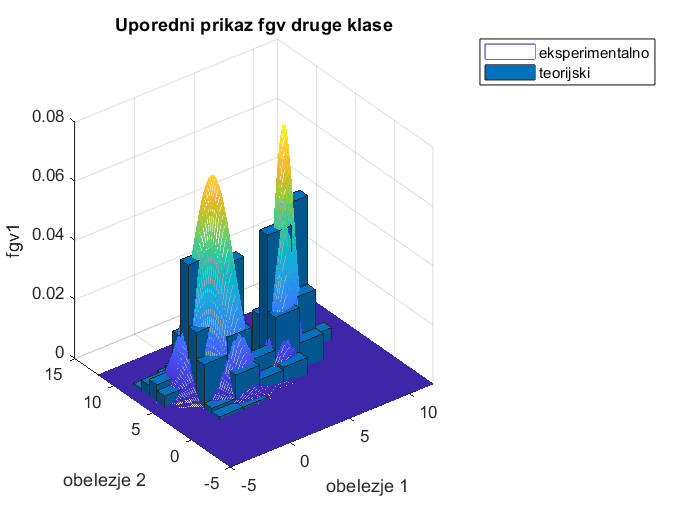

fig_id = fig_id+1;

figure(fig_id)
mesh(X,Y,f2,'FaceAlpha',0.5)
hold on;
histogram2(K2(:,2),K2(:,1),'Normalization','pdf');
xlabel('obelezje 1')
ylabel('obelezje 2')
zlabel('fgv1')
title('Uporedni prikaz fgv druge klase')
legend('eksperimentalno','teorijski')

fig_id = fig_id+1;

Vidimo da se procena fgv relativno poklapa sa teorijskom ali nije bas najsjajnija. Bila bi bolja kada bismo imali vise podataka. Bajesov klasifikator minimalne verovatnoce greske donosi odluku na osnovu aposteriorne verovatnoce, i Bajesove teoreme. On minimizuje verovatnocu ukupne greske podesavanjem optimalnog praga odlucivanja. Greska e2 se racuna u oblasti gde je doneta odluka 1 preko fgv druge klase. Analogno za e1. Sve procene se rade iskljucivo nad obucavajucim skupom.

Xs = [K1' K2'];
[e1_b, e2_b] = calc_e_theory(k,1,x,y,f1,f2);
[err1_b, err2_b] = calc_e_exp(Xs, M11, M12, M21,M22,S11,S12, S21,S22);

Confusion matrix
   498     2
     4   496



disp_error(e1_b,e2_b,err1_b,err2_b);

                    greska prvog reda    greska drugog reda
                    _________________    __________________

    pravi podaci            0.004                0.008     
    teorijski           0.0070182            0.0067827     



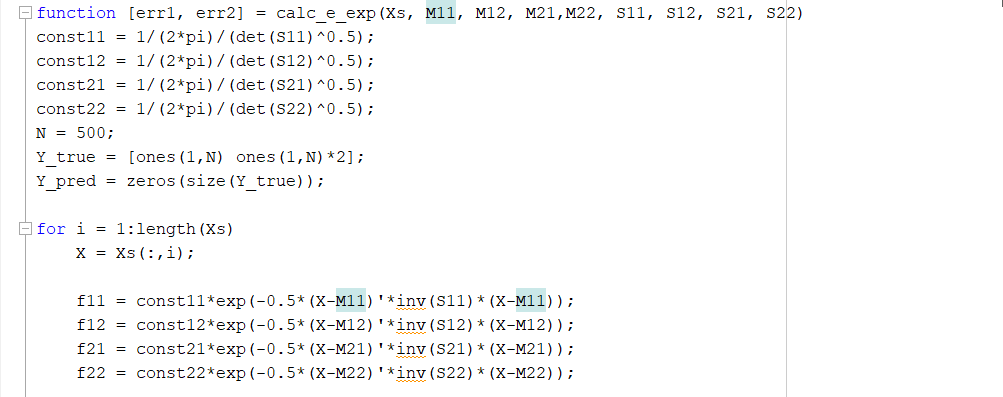

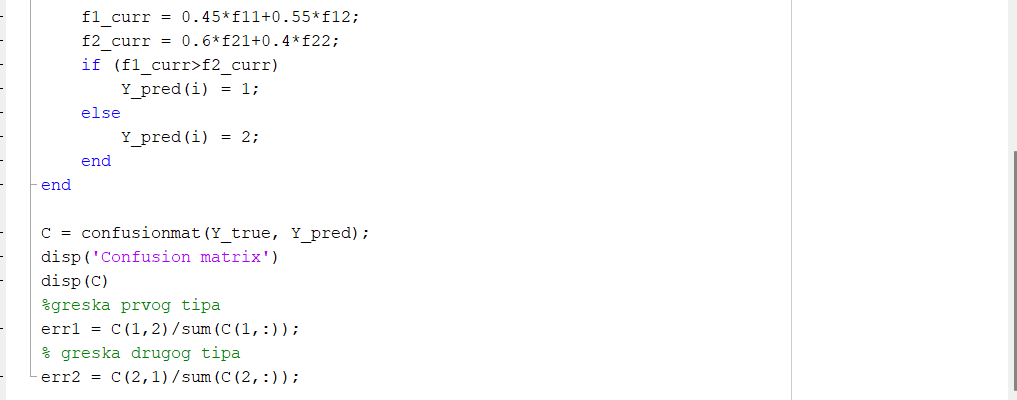

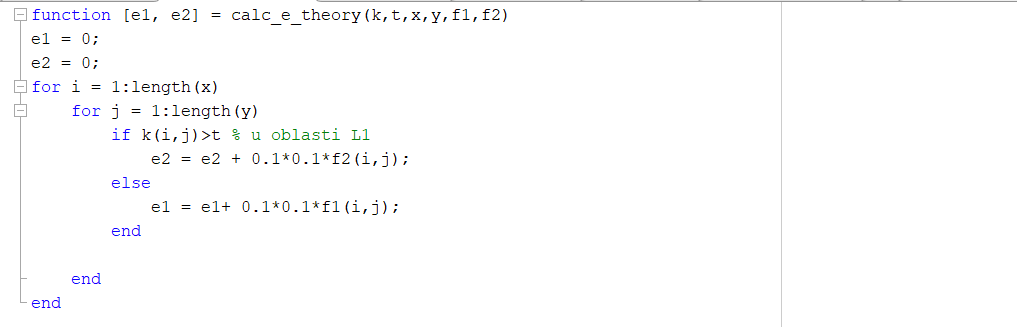

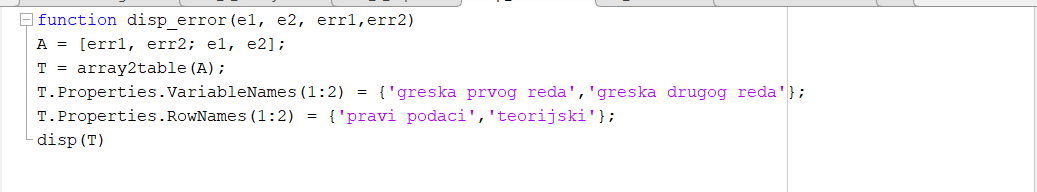

Greska klasifikacije se racuna nad test skupom.  Vidimo da se teorijska i eksperimentalna greska drugog reda poprilicno poklapaju ali eksperimentalna greska prvog reda poprilicno odstupa od teorijske.  Konfuziona matrica nam pokazuje da nas klasifikator radi dobro posao sa TPR = 99.6%, TNR = 99.2% i ACC = 99.4%.

### Bajesov klasifikator minimalne cene

Ovaj klasifikator nam daje mogucnost da vise kaznimo gresku pri klasifikaciji jedne klase u odnosu na drugu. Ovo je bitno kada imamo neki problem gde su posledice greske neke klase tragicne, poput analize podataka u medicini kada nam je bitnije da bolesnog pacijenta prepoznamo na vreme nego da zdravom pacijentu kazemo da je zdrav.

U ovu svrhu se definisu cene gde je cena Cij cena koju placamo kada odbirak koji zapravo pripada klasi j smestimo u klasu i. S obzirom da je zahtev zadatka da se vise penalizuje pogresna klasifikacija prve klase postavicemo C21 na vecu vrednost u odnosu na C12, dok C11 i C22 mogu biti nula jer oni oznacavaju da je odbirak dobro klasifikovan.

Ovime se klasifikaciona linija pomera dalje od klase 1 a blize klasi 2.

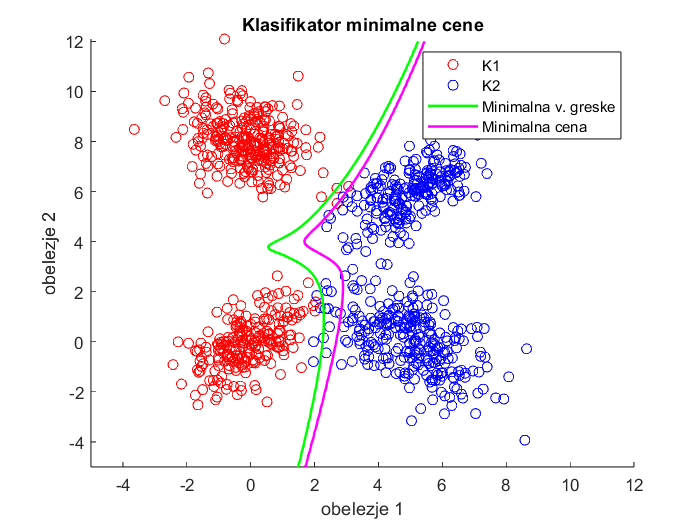

c11 = 0; c22 = 0;
% penalizing K1 misclassification
c12 = 1; c21 = 10; 
t = (c12-c22)/(c21-c11);

figure(fig_id)
hold all;
scatter(K1(:,1),K1(:,2),'ro');
scatter(K2(:,1),K2(:,2),'bo');
contour(x,y,k',[1,1],'g','LineWidth',1.5)
contour(x,y,k',[t t],'m','LineWidth',1.5);
legend('K1','K2','Minimalna v. greske','Minimalna cena')
xlabel('obelezje 1')
ylabel('obelezje 2')
title('Klasifikator minimalne cene')

fig_id = fig_id+1;

Vidimo da ovaj klasifikator pomera granicu ka klasi 2 u odnosu na prosli tako da elementi klase 1 budu bolje klasifikovani na ustrb toga da veci deo elemenata klase 2 bude lose klasifikovan u odnosu na malo pre.

[e1_c, e2_c] = calc_e_theory(k,t,x,y,f1,f2);
[err1_c, err2_c] = calc_e_exp(Xs, M11, M12, M21,M22,S11,S12, S21,S22);

Confusion matrix
   498     2
     4   496



disp_error(e1_c,e2_c,err1_c,err2_c);

                    greska prvog reda    greska drugog reda
                    _________________    __________________

    pravi podaci            0.004                0.008     
    teorijski           0.0014825             0.023017     



Iz matrice konfuzije se moze primetiti da je greska drugog tipa mnogo porasla dok je greska prvog tipa postala 0. Menjanjem C21 mogu se postici razlicite vrednosti ovih gresaka. Sto je vece C21 to ce biti manja greska prvog tipa i veca gresa drugog tipa i obrnuto.

### Neuman Pearson-ov klasifikator

Ovaj klasifikator se koristi kada nam je bitno da obe greske budu razumne, da se ne bi desilo da smanjivanjem greske prvog tipa kao malo pre previse pogorsamo gresku drugog tipa. Resenje ovoga je da gresku drugog tipa postavimo na konstantnu vrednost i uporedo smanjujemo gresku prvog tipa. Ovime smo osigurali da greska drugog tipa nece otici iznad razumne vrednosti.

Faktor mu koji figurise kao parametar, odredjujemo tako sto konstantu kojoj je jednaka greska drugog tipa stavljamo na vrednost bajesove greske, zato sto je bajesova greska najbolja procena ukupne greske a greska drugog tipa ne moze biti veca od ukupne pa je to dovoljno dobra procena.

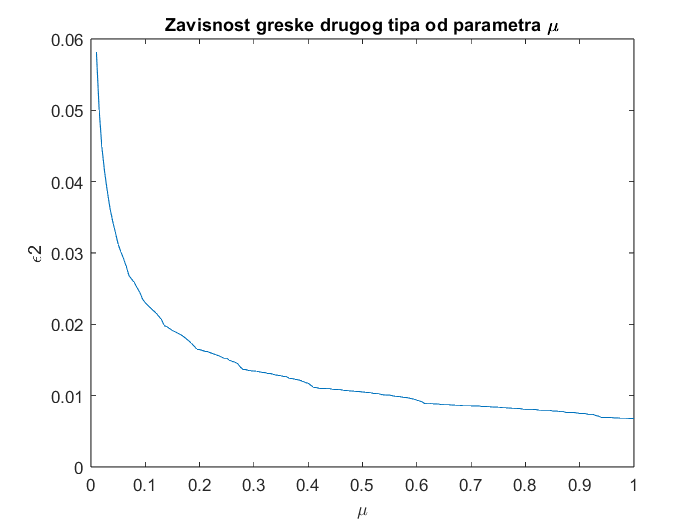

br = 0;
mii = 0.01:0.005:1;
for mi = mii
    br = br+1;
    [Eps1(br),Eps2(br)] = calc_e_theory(k,mi,x,y,f1,f2);
    
 end
 figure(fig_id)
 plot(mii,Eps2);
 xlabel('\mu');
 ylabel('\epsilon2')
 title('Zavisnost greske drugog tipa od parametra \mu')

 fig_id = fig_id+1;
 Eps = (e1_b+e2_b)/2;

id = find(Eps2<=Eps);
e1_n = Eps1(id(1));
e2_n = Eps2(id(1));
mu = mii(id(1));
disp(['Izabrano mu: ' num2str(mu) ', a greska drugog reda za to mu: ' num2str(Eps2(id(1)))]);

Izabrano mu: 0.965, a greska drugog reda za to mu: 0.0068751


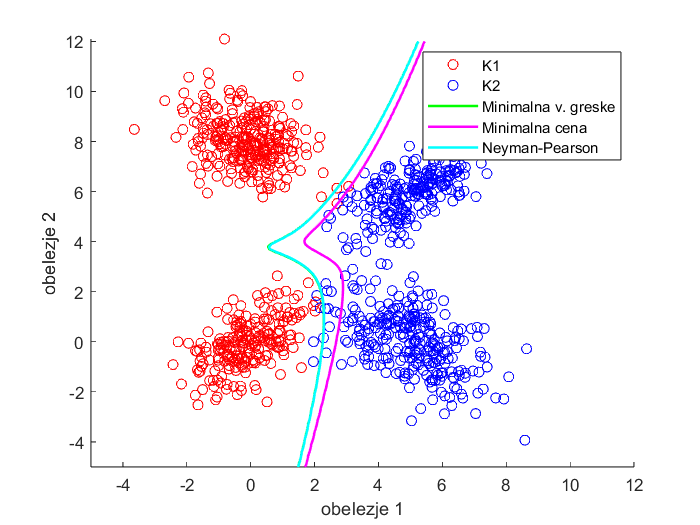


figure(fig_id)
hold all;
scatter(K1(:,1),K1(:,2),'ro');
scatter(K2(:,1),K2(:,2),'bo');
contour(x,y,k',[1,1],'g','LineWidth',1.5)
contour(x,y,k',[t t],'m','LineWidth',1.5);
contour(x,y,k',[mu, mu],'c','LineWidth',1.5);
legend('K1','K2','Minimalna v. greske','Minimalna cena', 'Neyman-Pearson')
xlabel('obelezje 1')
ylabel('obelezje 2')


fig_id = fig_id+1;

Vidimo da Nayman-Pearsonov-a klasifikaciona linija je ostala skoro ista kao kod Bajesa zato sto Bajes vec dovoljno dobro klasifikuje prvu klasu i ako bismo smanjili ovu gresku postalo bi pogubno po drugu klasu cime se resava problem od malo pre.

[err1_n, err2_n] = calc_e_exp(Xs, M11, M12, M21,M22,S11,S12, S21,S22);

Confusion matrix
   498     2
     4   496



disp_error(e1_n,e2_n,err1_n,err2_n);

                    greska prvog reda    greska drugog reda
                    _________________    __________________

    pravi podaci           0.004                 0.008     
    teorijski           0.006927             0.0068751     



Ocekivano, teorijska greska drugog reda je jednaka konstanti, a eksperimentalne greske ostaju iste kao kod bajesa zato sto nije moguce postici bolji rezultat od toga za ovaj set podataka.

### Wald-ov sekvencijalni klasifikator

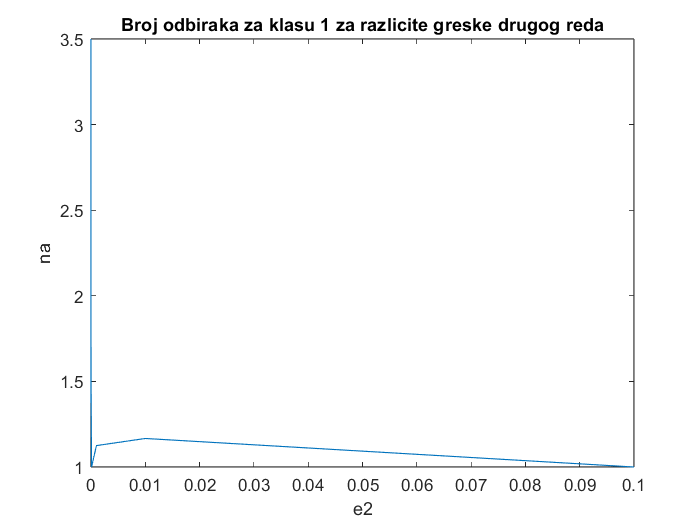

M = 15;
na = zeros(1,M);
nb = zeros(1,M);
eps1 = 0.07;
eps2 = 0.07;
eps = 10.^([-15:-1]);
for i = 1:M  
  [na(i), nb(i)] = wald(eps1,eps(i), M11, M12, M21, M22, S11,S12,S21,S22);
end

figure(fig_id)
plot(eps,na)
fig_id = fig_id+1;
title('Broj odbiraka za klasu 1 za razlicite greske drugog reda')
xlabel('e2')
ylabel('na')

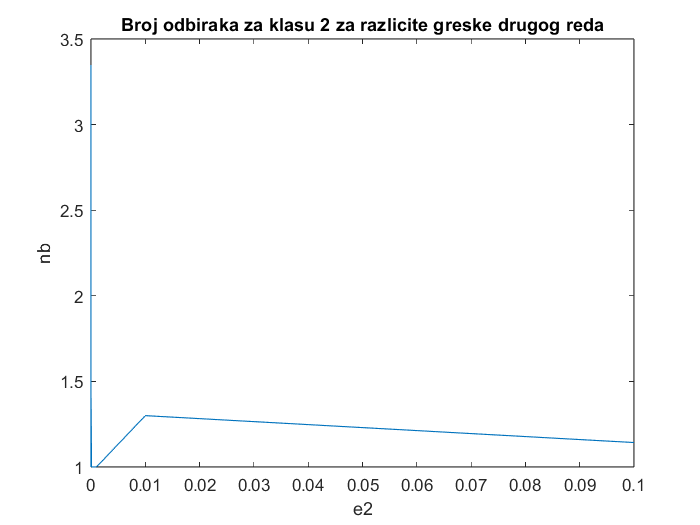


figure(fig_id)
plot(eps,nb)
title('Broj odbiraka za klasu 2 za razlicite greske drugog reda')
xlabel('e2')
ylabel('nb')

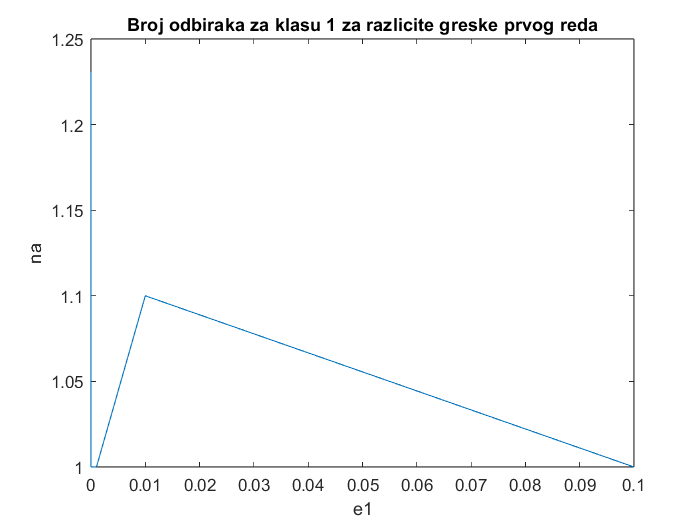

fig_id = fig_id+1;


for i = 1:M  
  [na(i), nb(i)] = wald(eps(i),eps2, M11, M12, M21, M22, S11,S12,S21,S22);
end

figure(fig_id)
plot(eps,na)
fig_id = fig_id+1;
title('Broj odbiraka za klasu 1 za razlicite greske prvog reda')
xlabel('e1')
ylabel('na')

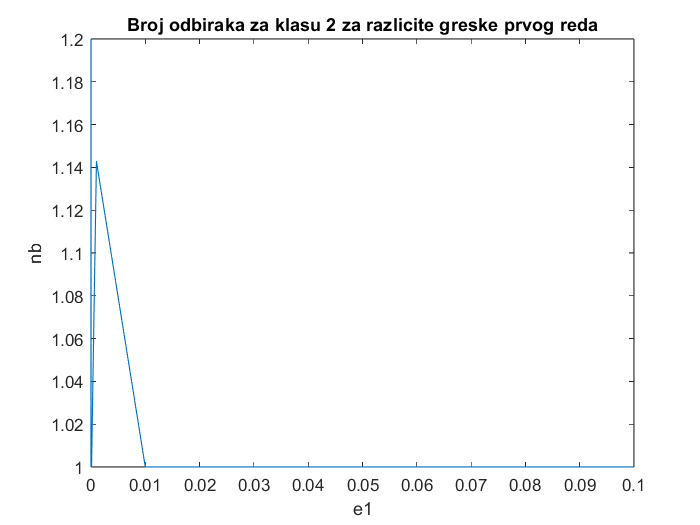

figure(fig_id)
plot(eps,nb)
title('Broj odbiraka za klasu 2 za razlicite greske prvog reda')
xlabel('e1')
ylabel('nb')

fig_id = fig_id+1;